## Problem 0

Download the .mat file 

load('Homework1.mat');

## Problem 1

Generate two sets of 1,000 random numbers that are drawn from the normal distribution (Hint: `randn`). Create a scatter plot of the first set of numbers against the second set of numbers. Label the two axes as "Condition A" and "Condition B". Show the resulting figure.

[`rand`](https://www.mathworks.com/help/matlab/ref/rand.html)`  - `Uniformly distributed random numbers

[`randn`](https://www.mathworks.com/help/matlab/ref/randn.html)` - `Normally (Gaussian) distributed random numbers whose values theoretically lies between `-``Infinity` to `Infinity` having `0` mean and `1` variance.

[https://www.mathworks.com/help/matlab/ref/scatter.html](https://www.mathworks.com/help/matlab/ref/scatter.html)

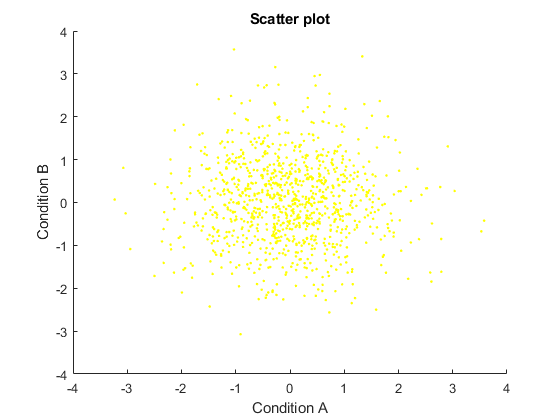

size = 1000;

% Generate normally distributed random numbers
set1 = randn(1, size);
set2 = randn(1, size);

% Create a scatter plot with circles at the locations specified by the vectors set1 and set2
scatter(set1, set2, 'yellow', '.');

title('Scatter plot');

% Label the two axes as "Condition A" and "Condition B"
xlabel('Condition A');
ylabel('Condition B');

## Problem 2

The data1 variable in Homework1.mat is a matrix of dimensions 2 x 20. Sum the numbers in each row and then compute the ratio between the two sums (i.e. sum of row 1 divided by sum of row 2. Store the answer in a variable called result and echo the value of this variable to the screen.

[https://www.mathworks.com/help/matlab/ref/sum.html](https://www.mathworks.com/help/matlab/ref/sum.html)

[https://www.mathworks.com/matlabcentral/answers/105090-how-to-calculate-the-sum-of-each-row-in-a-matrix](https://www.mathworks.com/matlabcentral/answers/105090-how-to-calculate-the-sum-of-each-row-in-a-matrix)

data1

data1 =     28    32    26     4     8    37    37    34    15    60    14     4    52     3    20    13    24    38    51    14
    82    18    92    86     5    37    89    83    52    79    56    58    36    31    82    66    30    16    80    94



% Calculate sum of first row
sumRow1 = sum(data1(1,:));

% Calculate sum of second row
sumRow2 = sum(data1(2,:));

% Calculate the result
result = sumRow1 / sumRow2

result = 0.4386

## Problem 3.

The `timeA`,`valsA`, `timeB`,`valsB` variables in Homework1.mat represent time-series data for two signals, A and B. The time points at which A was measured are given in `timeA`, and the corresponding measurements are given in `valsA`. (The same goes for B, `timeB`, and `valsB`.) Create a figure in which both signals are plotted as lines. Use a red line for A and a green line for B. Label the two axes and add a title and legend to the figure. Show the resulting figure.

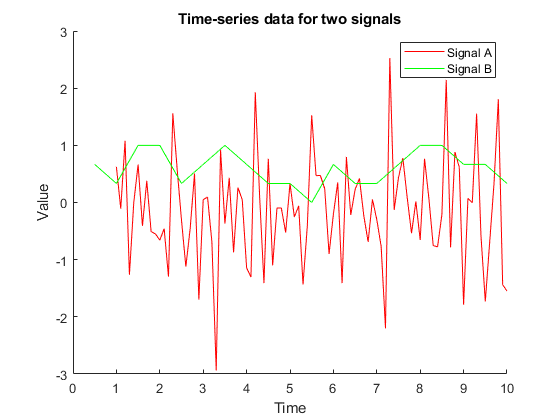

figure;

hold all;

title('Time-series data for two signals');

xlabel('Time');
ylabel('Value');

hA = plot(timeA, valsA, 'r-');
hB = plot(timeB, valsB, 'g-');

legend([hA hB],{'Signal A' 'Signal B'});

## **Problem 4.**

Create a variable containing the matrix shown to the right. Then, append a new row to the matrix that consists of all 1s. Then, change the top-right element of the matrix to 0. Finally, extract the last column of the matrix and reshape it to be a row vector. Store this vector in a variable called `result `and echo the value of this variable to the screen.

array = [3 -1 1.5; 2 0 0; 1 1 1];

array(end+1,:) = 1

array =     3.0000   -1.0000    1.5000
    2.0000         0         0
    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000


array(1, end) = 0

array =      3    -1     0
     2     0     0
     1     1     1
     1     1     1



result = array(:,end)'

result =      0     0     1     1


## **Problem 5. **

Write a function called `checkpositive.m `that accepts a 2D matrix as input and outputs a row vector. The row vector should contain as many elements as there are rows in the 2D matrix, and each element should indicate whether the corresponding row in the 2D matrix contains all positive numbers (use 0 to indicate no and 1 to indicate yes). The function should also report the results to the command window; the report should look something like this:

`Row 1: no `

`Row 2: yes`

`...etc.`

x = [4 1 1; -1 0 0; 0 0 0; .1 .2 .1]

x =     4.0000    1.0000    1.0000
   -1.0000         0         0
         0         0         0
    0.1000    0.2000    0.1000



result = checkpositive(x); 

Row 1: yes
Row 2: no
Row 3: no
Row 4: yes


result

result = 1×4 logical array
   1   0   0   1
